% Leemos datos
clear;
clc;
clf;
rawData = readtable("leaf.csv");
data = rawData.Variables;

% Paso 1 - Recogemos y preparamos los datos a usar
classes = data(:,1);
samples = data(:,2);
numberOfClasses = data(end, 1);

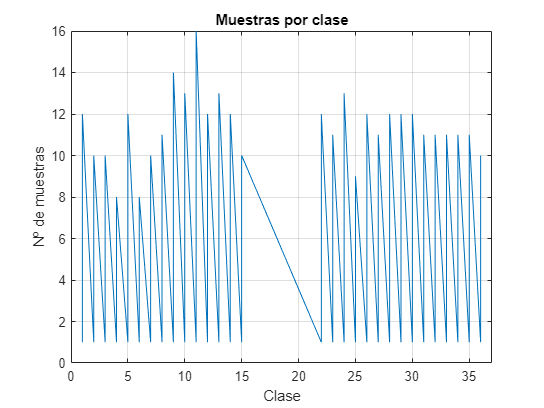

% Representamos datos iniciales
% Qué clase y cuántas muestras hay de c/u
plot(classes, samples)
grid on;
title("Muestras por clase");
xlabel("Clase");
ylabel("Nº de muestras");
xlim([0 37])
hold off;

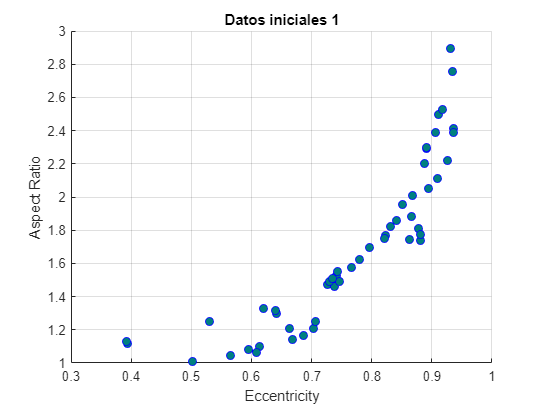


% Varias gráficas mostrando varias características
s = scatter(data(1:50,3), data(1:50,4));
s.LineWidth = 0.6;
s.MarkerEdgeColor = 'b';
s.MarkerFaceColor = [0 0.5 0.5];
grid on;
title("Datos iniciales 1");
xlabel("Eccentricity");
ylabel("Aspect Ratio");

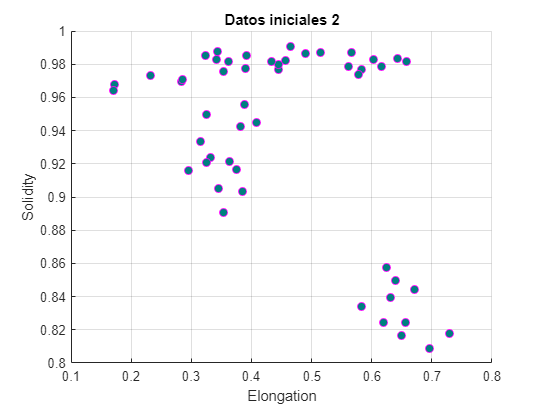


s2 = scatter(data(1:50,5), data(1:50,6));
s2.LineWidth = 0.6;
s2.MarkerEdgeColor = 'm';
s2.MarkerFaceColor = [0 0.5 0.5];
grid on;
title("Datos iniciales 2");
xlabel("Elongation");
ylabel("Solidity");

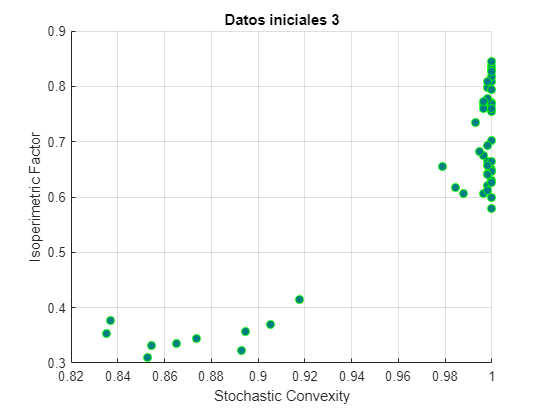


s3 = scatter(data(1:50,7), data(1:50,8));
s3.LineWidth = 0.6;
s3.MarkerEdgeColor = 'g';
s3.MarkerFaceColor = [0 0.5 0.5];
grid on;
title("Datos iniciales 3");
xlabel("Stochastic Convexity");
ylabel("Isoperimetric Factor");

% Arreglamos data para quitar las columnas 1,2 y 10-16
data(:,10:16) = [];
data(:,1:2) = [];
m = size(data, 1); % Filas o instancias
n = size(data, 2); % Columnas o dimensiones

% Paso 2 - Centramos datos y generamos matriz XC
XC = paso2(data);

% Paso 3 - Autovalores y autovectores de la matriz de covarianza
[eigenVectors, PCA, eigenValues] = paso3(XC, m);

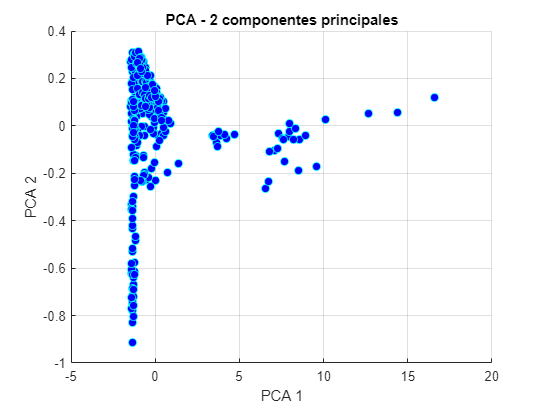

% Paso 4 - Representamos resultados
porcentajes = getPorcentajes(eigenValues);

s = scatter(PCA(:, 1), PCA(:, 2));
s.LineWidth = 0.6;
s.MarkerEdgeColor = '#07f8fc';
s.MarkerFaceColor = 'b';
title("PCA - 2 componentes principales");
xlabel("PCA 1");
ylabel("PCA 2");
grid on;

function XC = paso2(data)
    XC = zeros(size(data));
    % Restamos la media de cada componente
    media = mean(data, 1);
    for i = 1:size(data, 2)
        XC(:, i) = data(:, i) - media(i);
    end     
end

function [eigenVectors, PCA, eigenValues] = paso3(XC, m)
    % Calculamos la matriz de covarianza
    Z = (XC'*XC)/m;
    % Obtenemos sus autovalores y autovectores
    [eigenVectors, eigenValues] = eig(Z);
    % Ordenamos de forma decreciente según los autovalores
    [eigenValues, order] = sort(diag(eigenValues), 'descend');  
    eigenVectors = eigenVectors(:,order);
    % Obtenemos nuestros valores finales
    PCA = XC*eigenVectors;
end

function porcentajes = getPorcentajes(eigenValues)
    total = sum(eigenValues);
    porcentajes = (eigenValues/total);
    porcentajes = porcentajes.*100;
end